clc;
clear;

%%%% getting path
% addpath(genpath('xytheta'));

load('femm_output_sensor_r48_20220531_1937.mat')

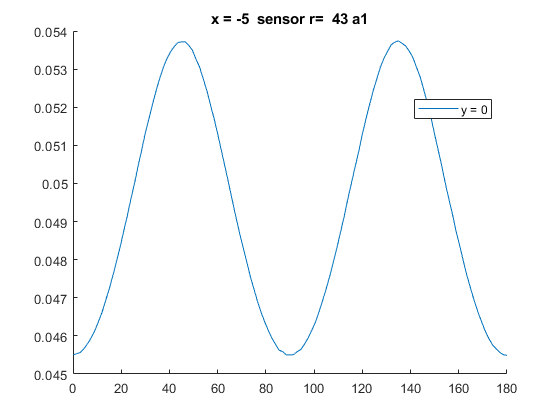

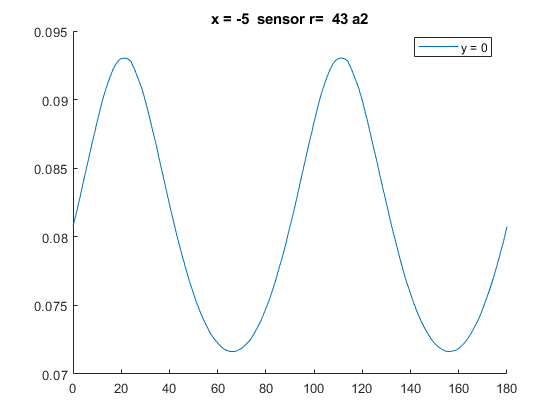

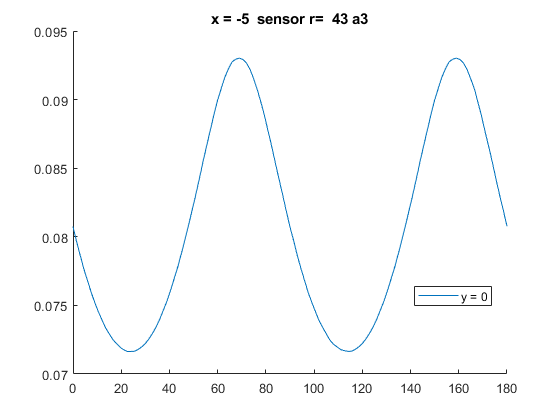

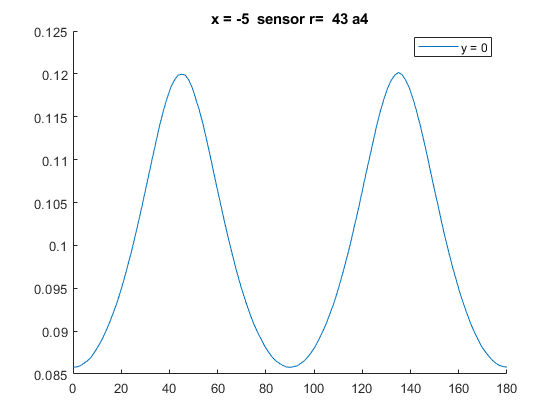

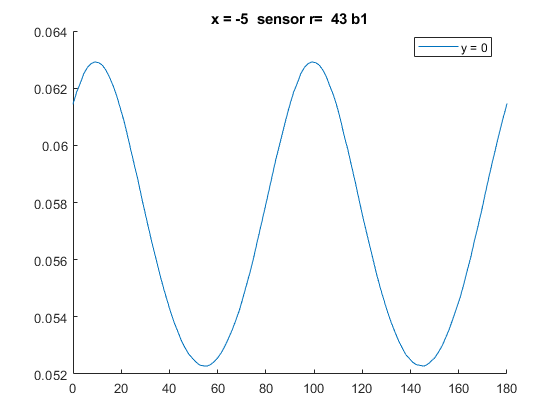

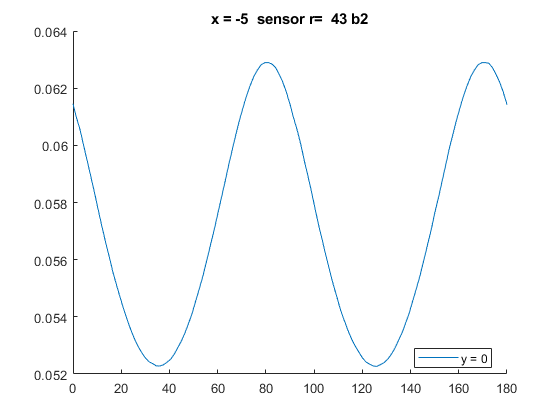

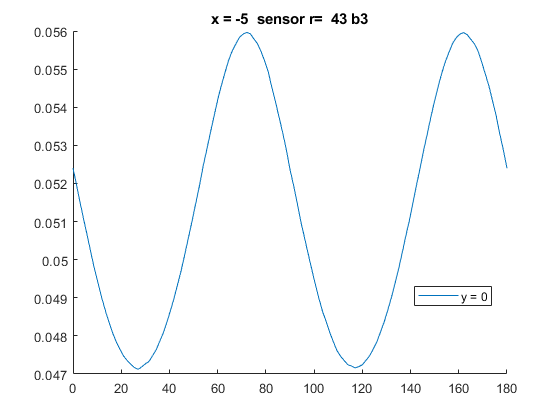

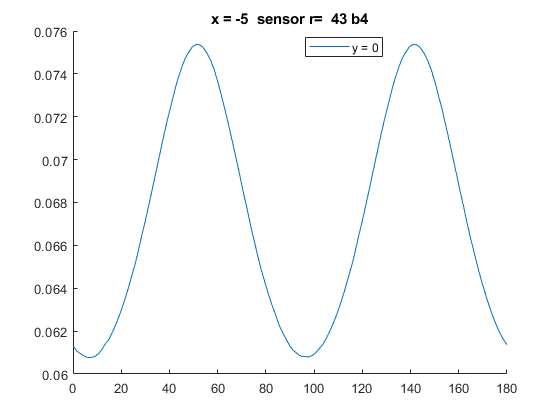

% a1a2a3a4 b1b2b3b4 c1c2c3c4
% too many figures

for m = x_index
    for n = 1:1:4
        f(n,m) = figure; %a
        hold on;
        legend("off")
        legend("show",Location="best")
        title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' a',num2str(n)])
        f(n+4,m) = figure; %b
        hold on;
        legend("off")
        legend("show",Location="best")
        title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' b',num2str(n)])
        f(n+8,m) = figure; %c
        hold on;
        legend("off")
        legend("show",Location="best")
        title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' c',num2str(n)])
    end
end

for m = x_index
    for n = y_index
        figure(f(1,m));
        plot(theta_r_in,a1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(2,m));
        plot(theta_r_in,b1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(3,m));
        plot(theta_r_in,c1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(4,m));
        plot(theta_r_in,a2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(5,m));
        plot(theta_r_in,b2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(6,m));
        plot(theta_r_in,c2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(7,m));
        plot(theta_r_in,a3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(8,m));
        plot(theta_r_in,b3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(9,m));
        plot(theta_r_in,c3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(10,m));
        plot(theta_r_in,a4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(11,m));
        plot(theta_r_in,b4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f(12,m));
        plot(theta_r_in,c4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
    end
end

max_peak_flux = zeros(length(x_index),length(y_index));
min_peak_flux = zeros(length(x_index),length(y_index));


for x = x_index
    for y = y_index
        max_arr = [max(abs(a1(:,x,y))),max(abs(a2(:,x,y))),max(abs(a3(:,x,y))),max(abs(a4(:,x,y))), ...
            max(abs(b1(:,x,y))),max(abs(b2(:,x,y))),max(abs(b3(:,x,y))),max(abs(b4(:,x,y))) ...
            ,max(abs(c1(:,x,y))),max(abs(c2(:,x,y))),max(abs(c3(:,x,y))),max(abs(c4(:,x,y)))];
        max_peak_flux(x,y) = max(max_arr);
        min_peak_flux(x,y) = min(max_arr);
        diff = a1(:,x,y)-a2(:,x,y);
    end
end

max_peak_flux'

ans =     0.5541    0.3966    0.3130    0.2590    0.2200    0.1908    0.1673    0.1487    0.1331    0.1202    0.1089    0.0993    0.0910    0.0836    0.0771    0.0836    0.0910    0.0993    0.1089    0.1202    0.1331    0.1487    0.1673    0.1908    0.2200    0.2590    0.3130    0.3966    0.5541


min_peak_flux'

ans =     0.0317    0.0334    0.0353    0.0373    0.0395    0.0418    0.0444    0.0472    0.0503    0.0537    0.0575    0.0616    0.0663    0.0714    0.0771    0.0714    0.0663    0.0616    0.0575    0.0537    0.0503    0.0473    0.0444    0.0418    0.0395    0.0373    0.0353    0.0334    0.0317


dif_max_flux =max_peak_flux'-min_peak_flux'

dif_max_flux =     0.5224    0.3632    0.2777    0.2218    0.1805    0.1489    0.1229    0.1014    0.0828    0.0664    0.0514    0.0377    0.0247    0.0122    0.0000    0.0122    0.0247    0.0377    0.0514    0.0664    0.0828    0.1014    0.1229    0.1489    0.1805    0.2218    0.2777    0.3632    0.5224


max_flux = max(max(max_peak_flux))

max_flux = 0.5541

min_flux = min(min(min_peak_flux))

min_flux = 0.0317


fine_x= find(max_peak_flux'*25-2.5 <0,1)

fine_x = 12

x_position(fine_x)

ans = -3

dq = 2/3*[1 -0.5 -0.5;0 sqrt(3)/2 -sqrt(3)/2;1/2 1/2 1/2]

dq =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774
    0.3333    0.3333    0.3333



alpha = zeros(4,length(theta_r_index),length(x_index),length(y_index));
beta = zeros(4,length(theta_r_index),length(x_index),length(y_index));
gamma = zeros(4,length(theta_r_index),length(x_index),length(y_index));
for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            alpha(1,r,x,y)=dq(1,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            alpha(2,r,x,y)=dq(1,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            alpha(3,r,x,y)=dq(1,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            alpha(4,r,x,y)=dq(1,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            beta(1,r,x,y)=dq(2,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            beta(2,r,x,y)=dq(2,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            beta(3,r,x,y)=dq(2,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            beta(4,r,x,y)=dq(2,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            gamma(1,r,x,y)=dq(3,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            gamma(2,r,x,y)=dq(3,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            gamma(3,r,x,y)=dq(3,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            gamma(4,r,x,y)=dq(3,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
        end
    end
end

x12 = zeros(length(theta_r_index),length(x_index),length(y_index));
y12 = zeros(length(theta_r_index),length(x_index),length(y_index));
x34 = zeros(length(theta_r_index),length(x_index),length(y_index));
y34 = zeros(length(theta_r_index),length(x_index),length(y_index));

xhat = zeros(length(theta_r_index),length(x_index),length(y_index));
yhat = zeros(length(theta_r_index),length(x_index),length(y_index));

for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            x12(r,x,y) = alpha(1,r,x,y)*gamma(1,r,x,y)-alpha(2,r,x,y)*gamma(2,r,x,y);
            y12(r,x,y) = beta(1,r,x,y)*gamma(1,r,x,y)-beta(2,r,x,y)*gamma(2,r,x,y);
            x34(r,x,y) = cos(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))-sin(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));
            y34(r,x,y) = sin(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))+cos(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));

        end
    end
end

%%kg calculation x=1, y=0 fixed point
    
    x_mid = median(x_index);
    y_mid = median(y_index);
    checkx1y0 = x12(:,x_mid+1,y_mid)+x34(:,x_mid+1,y_mid);
    mean(checkx1y0);
    kg = round(1/mean(checkx1y0))

kg = 750


for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            xhat(r,x,y) = kg*(x12(r,x,y)+x34(r,x,y));
            yhat(r,x,y) = -kg*(y12(r,x,y)+y34(r,x,y));
        end
    end
end

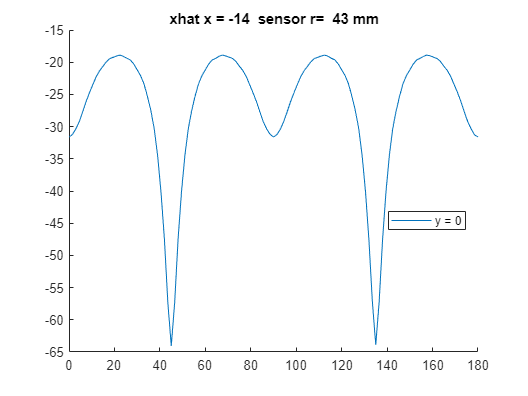

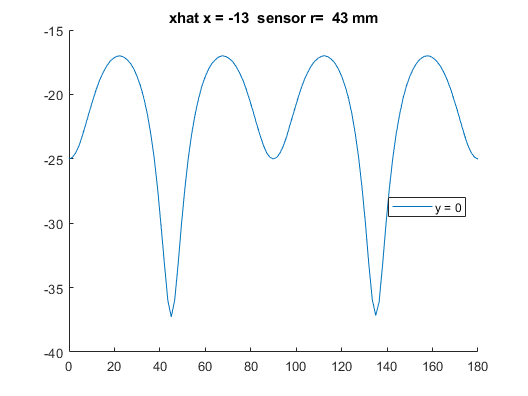

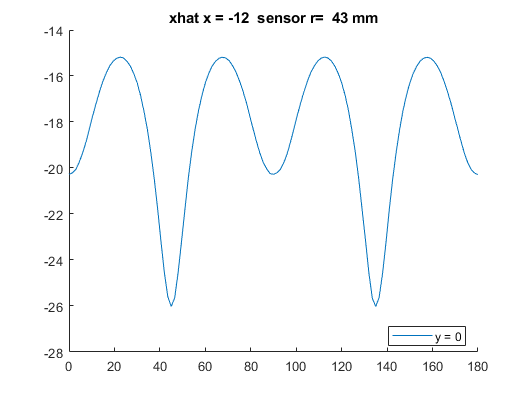

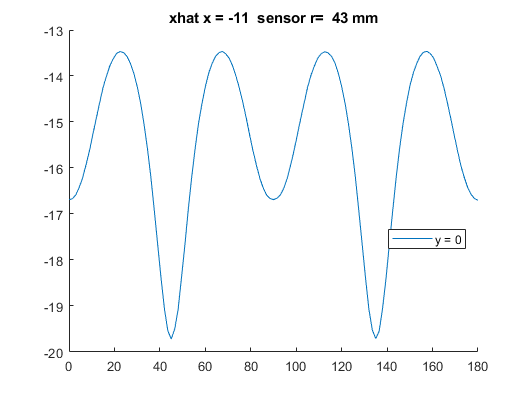

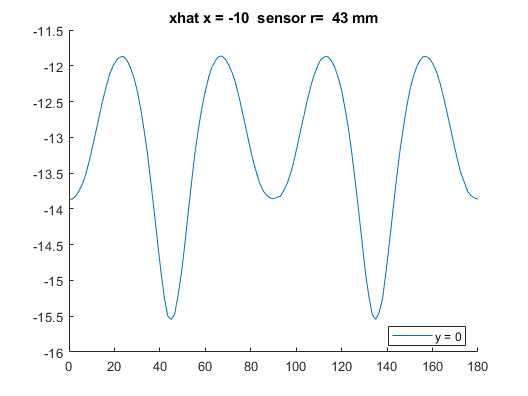

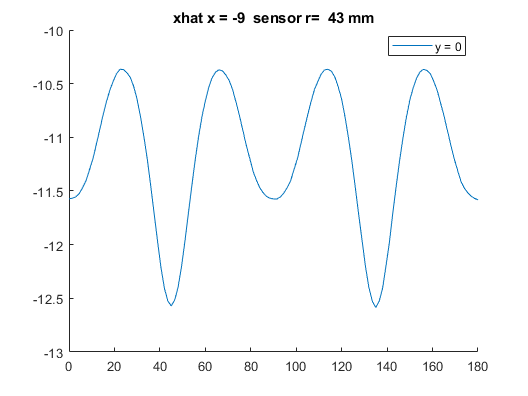

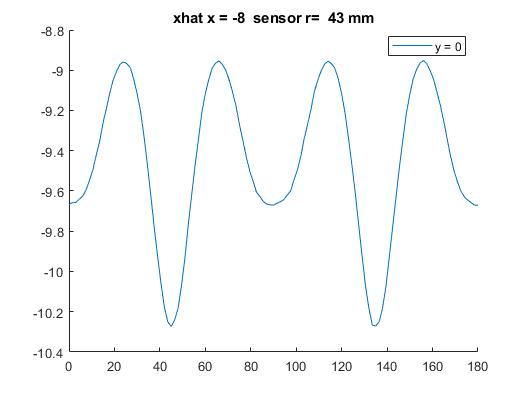

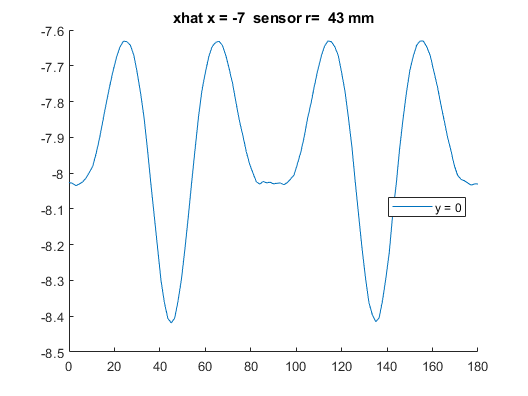

f2 = zeros(length(x_index),2);

for m = x_index
        f2(m,1) = figure; %a
        hold on;
        legend("off")
        legend("show",Location="best")
        title(['xhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' mm'])
%         f2(m,2) = figure;
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['yhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' mm'])
    for n = y_index
        figure(f2(m,1));
        plot(theta_r_in,xhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f2(m,2));
%         plot(theta_r_in,yhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
    end
end

full_figure = figure;
hold on;
grid on;
title(['sensor_r = ',num2str(sensor_r)])
xlim([-20,20])
ylim([-5,5])
for m = x_index
    for n = y_index
        scatter(xhat(:,m,n),yhat(:,m,n),2)
    end
end



filename = sprintf('xytheta_output_sensor_r%d_kg%d_%s.mat',sensor_r,kg,date)

filename = 'xytheta_output_sensor_r43_kg750_20220529_2335.mat'

save(filename)